clear all
close all;
clc;
% Tf Generation
m1=1;
m2=1;
k1=(86+1)/15;
b2=k1;
k2=(1+86)/100;
b1=k2;
k3=k2/2;
A=[0 1 0 0;
    -(k1+k3)/m1 -b1/m1 k3/m1 0;
    0 0 0 1;
    k3/m2 0 -(k2+k3)/m2 -b2/m2];
B=[0 ;1/m1 ;0 ;0]; 
C=[1 0 1 0]; 
D=0;
[b,a]= ss2tf(A,B,C,D);
sys=tf(b,a);
fb = bandwidth(sys);
Ts=0.05*2*pi/fb; %seconds
sysd = c2d(sys, Ts,'zoh');
[c,d]=tfdata(sysd,'v');

N_samples=500;
t=0:Ts:Ts*N_samples;
tt=size(t,2);
u=[0 0 0 0 ones(1,tt-5)];
%%noise=[0,0,0,0,.01*randn(1,tt-5)];
%%u=noise-mean(noise)
%%u=u+noise;
%%u=noise
num=[c(2:5)];
den=d;
dd=[d(1,2:5)];
init=[dd,c];
% Sampling
y(1)=0;
y(2)=0;
y(3)=0;
y(4)=0;
y(5)=0;

for temp=6:N_samples
    y(temp)=[-(y(temp-1:-1:temp-4)),(u(temp:-1:temp-4))]*(init');
end

phi=[];

phi(1,:)=zeros(1,10)

phi =      0     0     0     0     0     0     0     0     0     0


phi(2,:)=zeros(1,10)

phi =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


phi(3,:)=zeros(1,10)

phi =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


phi(4,:)=zeros(1,10)

phi =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


phi(5,:)=zeros(1,10)

phi =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


for temp=6:N_samples
    phi(temp,:)=[-(y(temp-1:-1:temp-5)),(u(temp-1:-1:temp-5))];
end

 Y=y(1:end)';
theta_hat=((phi'*phi)^-1)*phi'*Y

theta_hat =    -2.6535
    1.6236
    1.0303
   -1.6092
    0.4432
    0.0040
    0.0009
   -0.0058
   -0.0008
    0.0019


%%normpara=norm(theta_hat-[den(2:end),num(2:end)]')
normy=norm(Y-phi*theta_hat)

normy = 0.7887

%%rmsd=sqrt(sum(((theta_hat-[den(2:end),num(2:end)]').^2)/8))

sysdd=tf([0,theta_hat(6:end)'],[1,theta_hat(1:5)'],Ts);
theta_hat

theta_hat =    -2.6535
    1.6236
    1.0303
   -1.6092
    0.4432
    0.0040
    0.0009
   -0.0058
   -0.0008
    0.0019


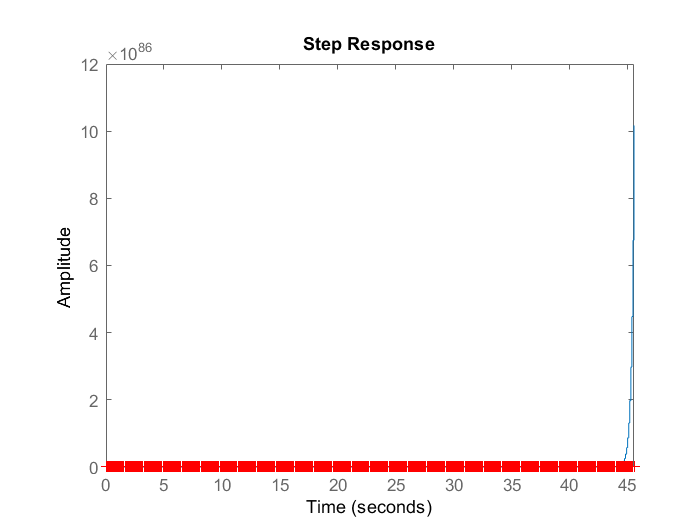

figure
step(sysdd,t)
hold on
step(sysd,t,'r+')

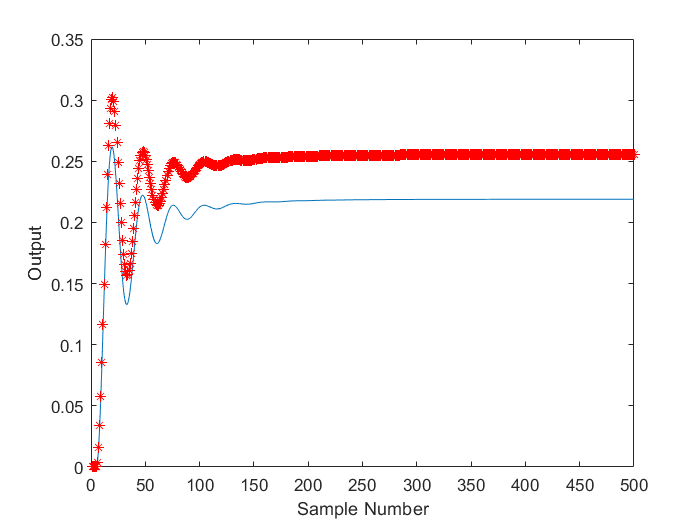

figure
plot(Y)
hold on
plot(phi*theta_hat,'r*')
xlabel('Sample Number')
ylabel('Output')